## Sistema de referencia inicial

clear

**Posición**

x = 0;
y = 0;
z = 0;
posicion = [x; y; z];

**Orientación**

phi = 0;    %Rotación en el eje X
theta = 0;  %Rotación en el eje Y
psi = 0;    %Rotación en el eje Z
orientacion = [phi; theta; psi];
secuencia = "XYZ";

## Leer información de la tablas

dh = readtable('datos\tabla_DH\robot7.csv');

## Ecuaciones de las articulaciones

% Convertir las columnas numéricas a double
thetaNum = deg2rad(double(dh.theta));
dNum     = double(dh.d);
aNum     = double(dh.a);
alphaNum = deg2rad(double(dh.alpha));
min = double(dh.min);
max = double(dh.max);

% Convertir la columna de tipo a char (se asume 'r' para revoluta y 'p' para prismática)
tipo = char(dh.tipo);

n = size(dh,1);  % Número de eslabones/juntas

**Matriz de transformación homogenea inicial**

R = euler2rotMat(orientacion,secuencia);
A0 = [R          posicion
      zeros(1,3) 1];

## Crear variables simbólicas según el tipo de articulación

q = sym(zeros(n,1));  % Preasignar vector simbólico
for i = 1:n
    if tipo(i) == 'r'
        % Junta revoluta: el ángulo es variable
        q(i) = sym(sprintf('theta_%d', i));
    elseif tipo(i) == 'p'
        % Junta prismática: el desplazamiento es variable
        q(i) = sym(sprintf('d_%d', i));
    else
        error('Tipo de articulación no reconocido en la fila %d.', i);
    end
end

## Construir las matrices de transformación homogénea simbólicas para cada eslabón

## 
$$A_i=R_{z,\theta_i}T_{z,d_i}T_{x,a_i}R_{x,\alpha_i}$$


% Se convierten los parámetros numéricos a simbólicos usando sym()
A = sym(zeros(4,4,n));  % Preasignar matriz simbólica para cada transformación
offset = zeros(n,1);
for i = 1:n
    % Para cada articulación, dependiendo del tipo se asigna la variable simbólica
    if tipo(i) == 'r'
        % Junta revoluta: θ es variable, d es fija
        theta_sym = q(i);
        offset(i) = deg2rad(thetaNum(i)); % Guarda el valor de la variable como offset
        d_sym = sym(dNum(i));
    elseif tipo(i) == 'p'
        % Junta prismática: d es variable, θ es fija
        theta_sym = sym(thetaNum(i));
        d_sym = q(i);
        offset(i) = dNum(i); % Guarda el valor de la variable como offset
    end
    a_sym     = sym(aNum(i));
    alpha_sym = sym(alphaNum(i));
    
    % Calcular la transformación homogénea para el eslabón i
    A(:,:,i) = simplify(HRz(theta_sym) * HTz(d_sym) * HTx(a_sym) * HRx(alpha_sym));
end

## Calcular la transformación homogénea acumulada (de la base al extremo)

## 
$$T_1^n =\prod_{i=1}^n A_i =A_1 A_2 \ldotp \ldotp \ldotp A_n$$


T = sym(zeros(4,4,n));
T(:,:,1) = sym(A0)*A(:,:,1);
for i = 2:n
    T(:,:,i) = simplify(T(:,:,i-1) * A(:,:,i));
end

## Graficar Robot

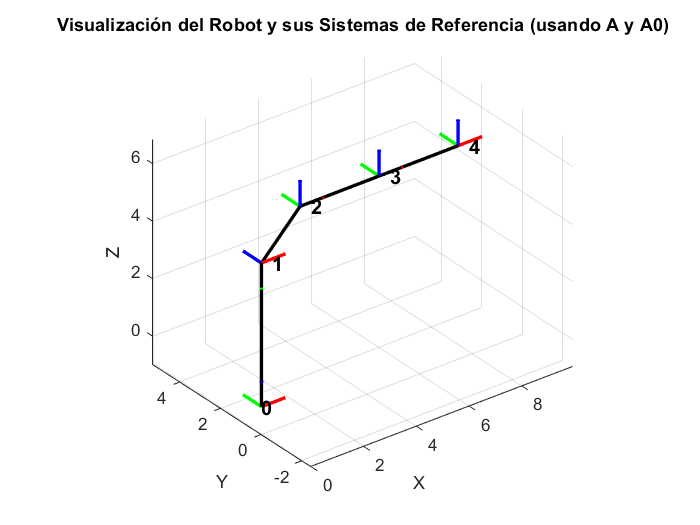

plotRobot(A, A0, offset, tipo, 1);

## Calcular jacobiano geométrico

#### Valores iniciales

% Inicializar las matrices para la parte traslacional (Jv) y rotacional (Jw)
Jv = sym(zeros(3, n));
Jw = sym(zeros(3, n));

% Posición del efector final (se extrae de la última transformación  T(:,:,end))
p_end = T(1:3, 4, end);

% Definir el origen y el eje z de la base
p0 = sym(A0(1:3, 4));   % vector de posición inicial
z0 = sym(A0(1:3, 3));   % La tercera columna de la submatriz de rotación inicial

for i = 1:n
    % Para i = 1, usar p0 y z0; para i > 1, extraer de T(:,:,i-1)
    if i == 1
        p_prev = p0;
        z_prev = z0;
    else
        p_prev = T(1:3, 4, i-1);
        z_prev = T(1:3, 3, i-1);  % La tercera columna de la submatriz de rotación
    end
    
    % Determinar la columna i del Jacobiano según el tipo de articulación
    if tipo(i) == 'r'
        % Junta revoluta:
        % Parte traslacional: z_prev x (p_end - p_prev)
        Jv(:, i) = simplify(cross(z_prev, p_end - p_prev));
        % Parte rotacional: z_prev
        Jw(:, i) = z_prev;
    elseif tipo(i) == 'p'
        % Junta prismática:
        % Parte traslacional: z_prev
        Jv(:, i) = z_prev;
        % Parte rotacional: cero
        Jw(:, i) = sym([0; 0; 0]);
    else
        error('Tipo de articulación no reconocido en la fila %d.', i);
    end
end

% Jacobiano geométrico completo: apilando las partes traslacional y rotacional
Jgeometrico = simplify([Jv; Jw],10)

% diff(the)
% velGeometrica = Jgeometrico*

R_end = T(1:3,1:3,end);
eta = simplify(rotMat2euler(R_end, 'XYZ'),10);
Janalitico = simplify(jacobian([p_end;eta],q),10)